clear

% Load the text file
filePath = 'chp13.txt'; % Change this to the correct path if needed
fileContent = fileread(filePath);

% Split the content into sentences using punctuation as delimiters
sentences = split(fileContent, newline);

% Trim any leading or trailing whitespace from each sentence
sentences = strtrim(sentences);

% Remove empty entries caused by consecutive delimiters
sentences = sentences(~cellfun('isempty', sentences));

% Display the sentences
disp('Extracted Sentences:');

Extracted Sentences:


disp(sentences);

    {'Page Ranking for a Web Search Engine.'                                                                                                                                                                                                                                                                           }
    {'When a search is made on the Internet using a search engine, there is first a traditional text processing part, where the aim is to find all the Web pages containing the words of the query.'                                                                                                                   }
    {'Due to the massive size of the Web, the number of hits is likely to be much too large to be of use.'                                                                                                                                                                                                             }
    {'Therefore, some measure of quality is needed to filter 



% Load the stop words (MATLAB has a built-in stop word list)
useStopWords = stopWords("Language", "en");

% Initialize an empty cell array to hold the processed words
allProcessedWords = {};

% Loop through each sentence
for n = 1:length(sentences)
    %--- Tokenize the sentence into words ---
    words = split(sentences{n});

    %--- Remove punctuation ---
    filteredWords = erasePunctuation(words);

    %--- Lower case all the words ---
    filteredWords = lower(filteredWords);
    
    % Remove tokens containing numbers
    filteredWords = filteredWords(~contains(words, digitsPattern)); % MATLAB's pattern matching for numbers

    %--- Remove stop words ---
    filteredWords = filteredWords(~ismember(filteredWords, useStopWords));

    %--- Stem the words ---
    stemmedWords = normalizeWords(filteredWords, "Language", "en");

    % Store processed words for each sentence
    allProcessedWords{n} = stemmedWords;
end

% Combine all unique words from all sentences
uniqueWords = unique(vertcat(allProcessedWords{:}))

uniqueWords = 499×1 cell array
    {0×0 char   }
    {'acceler'  }
    {'accept'   }
    {'accumul'  }
    {'actual'   }
    {'adapt'    }
    {'add'      }
    {'addit'    }
    {'adjac'    }
    {'afford'   }
    {'aggreg'   }
    {'agre'     }
    {'aim'      }
    {'aitken'   }
    {'algorithm'}
    {'alwai'    }
    {'among'    }
    {'analog'   }
    {'analys'   }
    {'analysi'  }
    {'anoth'    }
    {'answer'   }
    {'appli'    }
    {'applic'   }
    {'approxim' }
    {'arithmet' }
    {'arnoldi'  }
    {'artifici' }
    {'assign'   }
    {'assum'    }



% Remove any empty elements
uniqueWords = uniqueWords(~cellfun('isempty', uniqueWords))

uniqueWords = 498×1 cell array
    {'acceler'  }
    {'accept'   }
    {'accumul'  }
    {'actual'   }
    {'adapt'    }
    {'add'      }
    {'addit'    }
    {'adjac'    }
    {'afford'   }
    {'aggreg'   }
    {'agre'     }
    {'aim'      }
    {'aitken'   }
    {'algorithm'}
    {'alwai'    }
    {'among'    }
    {'analog'   }
    {'analys'   }
    {'analysi'  }
    {'anoth'    }
    {'answer'   }
    {'appli'    }
    {'applic'   }
    {'approxim' }
    {'arithmet' }
    {'arnoldi'  }
    {'artifici' }
    {'assign'   }
    {'assum'    }
    {'assumpt'  }



% Initialize term-document matrix
termDocumentMatrix = zeros(length(uniqueWords), length(sentences));

% Populate the term-document matrix
for n = 1:length(sentences)
    sentenceWords = allProcessedWords{n};
    for w = 1:length(uniqueWords)
        termDocumentMatrix(w, n) = sum(strcmp(uniqueWords{w}, sentenceWords));
    end
end

termDocumentMatrix

termDocumentMatrix =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

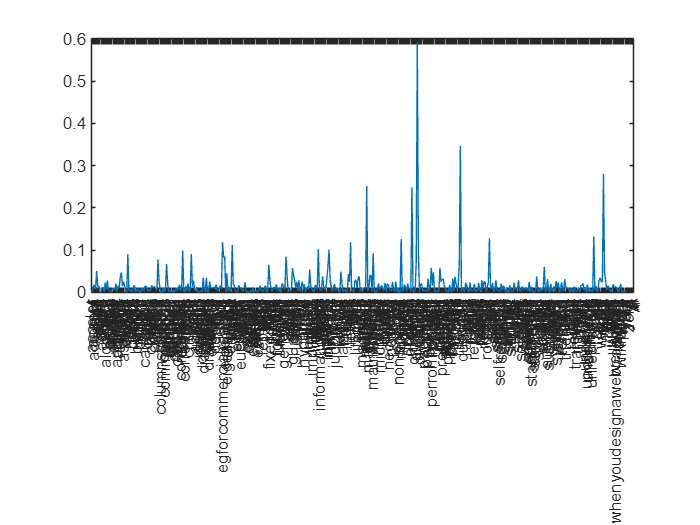

[u,s,v]=svds(termDocumentMatrix,1);

%Make u and v positive
u = abs(u);
v = abs(v);

plot(linspace(0,max(u),size(u,1)),u(:,1))
set(gca,'xtick',linspace(min(xlim),max(xlim),size(u,1)),'xticklabel',uniqueWords)

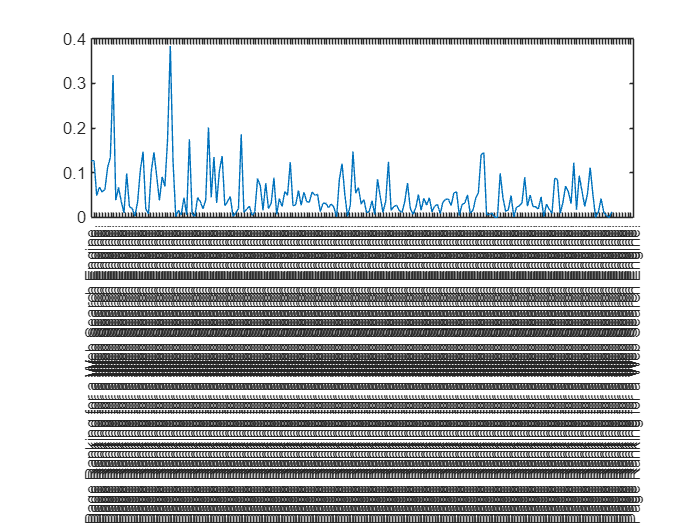


plot(linspace(0,max(v),size(v,1)),v(:,1))
set(gca,'xtick',linspace(min(xlim),max(xlim),size(v,1)),'xticklabel',sentences(1,:))


% Display the term-document matrix
disp('Term-Document Matrix:');

Term-Document Matrix:


disp(array2table(termDocumentMatrix, 'RowNames', string(uniqueWords), 'VariableNames', strcat("Sentence_", string(1:length(sentences)))));

                                  Sentence_1    Sentence_2    Sentence_3    Sentence_4    Sentence_5    Sentence_6    Sentence_7    Sentence_8    Sentence_9    Sentence_10    Sentence_11    Sentence_12    Sentence_13    Sentence_14    Sentence_15    Sentence_16    Sentence_17    Sentence_18    Sentence_19    Sentence_20    Sentence_21    Sentence_22    Sentence_23    Sentence_24    Sentence_25    Sentence_26    Sentence_27    Sentence_28    Sentence_29    Sentence_30    Sentenc

% Number of top values to extract
topN = 10; % Change this to the number of largest values you want

% Find the indices of the top N values
[~, originalIndices] = maxk(u(:,1), topN); % Finds the largest values and their original indices
topValues = u(originalIndices)      % Get the values at those indices

topValues =     0.5915
    0.3471
    0.2809
    0.2515
    0.2484
    0.1326
    0.1283
    0.1270
    0.1191
    0.1188


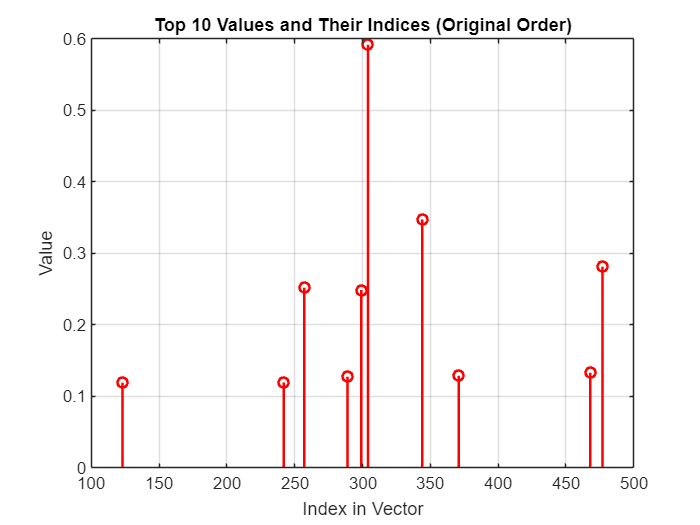


% Plot the indices
figure;
stem(originalIndices, topValues, 'r', 'LineWidth', 1.5); % Stem plot to highlight indices
title(['Top ', num2str(topN), ' Values and Their Indices (Original Order)']);
xlabel('Index in Vector');
ylabel('Value');
grid on;


% Display results
disp('Top Values:');

Top Values:


disp(topValues);

    0.5915
    0.3471
    0.2809
    0.2515
    0.2484
    0.1326
    0.1283
    0.1270
    0.1191
    0.1188



disp('Indices of Top Values:');

Indices of Top Values:


disp(uniqueWords(originalIndices));

    {'page'     }
    {'rank'     }
    {'web'      }
    {'matrix'   }
    {'outlink'  }
    {'vector'   }
    {'search'   }
    {'number'   }
    {'link'     }
    {'eigenvalu'}



## Rank-k approximation

[U, S, V] = svd(termDocumentMatrix,"econ");

% k is chosen greater than or equal to the number of key sentences we want
% to extract, ref. Eldén [164]
k = 10;

% Compute C and D
C = U(:,1:k) * S(1:k,1:k); % C = U_k * sigma_k
D = V(:,1:k)'; % D = V_k'
A_k = C * D; % Reconstructing termDocumentMatrix using rank-k approximation

% Using this method instead of the one on [167] in Eldén, which did not
% work
[~, ~, permVec] = qr(D, 'vector'); % 'vector' returns permutation as indices
pk = permVec(1:k); % Get the first k pivoted column indices

disp('Rank-k Approximation Results:');

Rank-k Approximation Results:



% Display top contributing sentences (columns with maximum contribution in A_k)
disp('Top Contributing Sentences (Columns with Maximum Contribution in A_k):');

Top Contributing Sentences (Columns with Maximum Contribution in A_k):


[~, maxIndices] = maxk(sum(A_k, 1), k);
disp('Indices of Sentences:');

Indices of Sentences:


disp(maxIndices);

    30   171     9    11     2   145   172    44   117   110



disp('Sentences:');

Sentences:


disp(sentences(maxIndices));

    {'To discourage this, one defines the rank of i so that if a highly ranked page j has an outlink to i, this adds to the importance of i in the following way: the rank of page i is a weighted sum of the ranks of the pages that have outlinks to i.'                                    }
    {'When computing the pagerank for a subset of the Internet, say, one particular domain, the matrix P may be of a dimension for which one can use methods other than the power method, e.g., the Arnoldi method; see [49] and Section 17.8.3.'                                             }
    {'The ranking procedure was based not on human judgment but on the link structure of the Web. Loosely speaking, Google assigned a high rank to a Web page if it had inlinks from other pages that have a high rank.'                                                                      }
    {'A Google search with the same search phrase made on February 6, 2019, gave the top result University - Wikipedia, which is a good 


% Display top words
disp('Top Words for Rank-k Approximation:');

Top Words for Rank-k Approximation:



disp('Top words:');

Top words:


[~, wordIndices] = maxk(C(:, k), 10);
disp(uniqueWords(wordIndices));

    {'pagerank' }
    {'method'   }
    {'equal'    }
    {'eigenvalu'}
    {'random'   }
    {'web'      }
    {'googl'    }
    {'power'    }
    {'get'      }
    {'matrix'   }




% Top sentences by QR decomposition (after rank-k)
disp('Top Contributing Sentences (from QR Decomposition):');

Top Contributing Sentences (from QR Decomposition):


disp('Indices of Sentences:');

Indices of Sentences:


disp(pk);

   179    44    30    11   171   106   121   134    97    77



disp('Sentences:');

Sentences:


disp(sentences(pk));

    {'The basic idea is that good hubs point to good authorities and good authorities are pointed to by good hubs.'                                                                                                                                       }
    {'Similarly, column j has nonzero elements equal to 1/Nj in the positions that correspond to the outlinks of j, and, provided that the page has outlinks, the sum of all the elements in column j is equal to one.'                                   }
    {'To discourage this, one defines the rank of i so that if a highly ranked page j has an outlink to i, this adds to the importance of i in the following way: the rank of page i is a weighted sum of the ranks of the pages that have outlinks to i.'}
    {'A Google search with the same search phrase made on February 6, 2019, gave the top result University - Wikipedia, which is a good answer for the highly underspecified search phrase.'                                                        